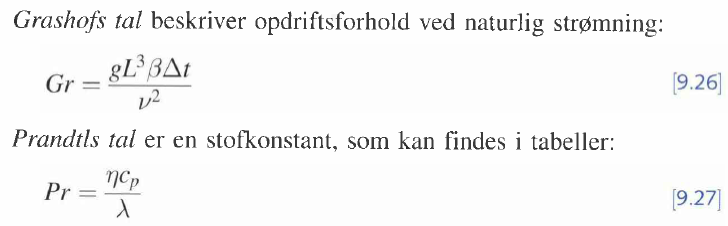

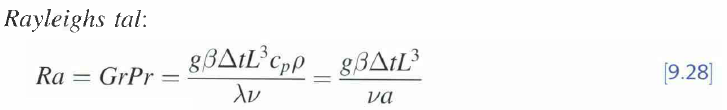

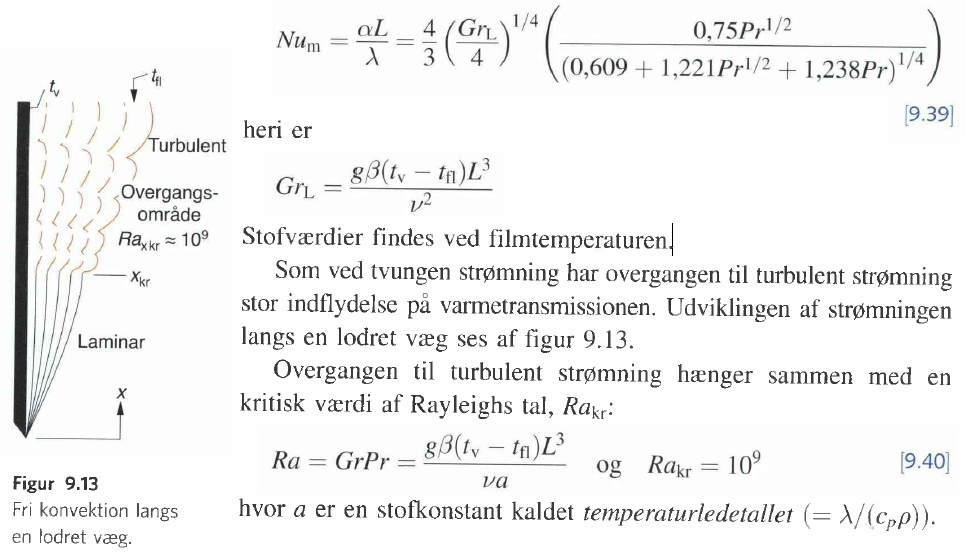

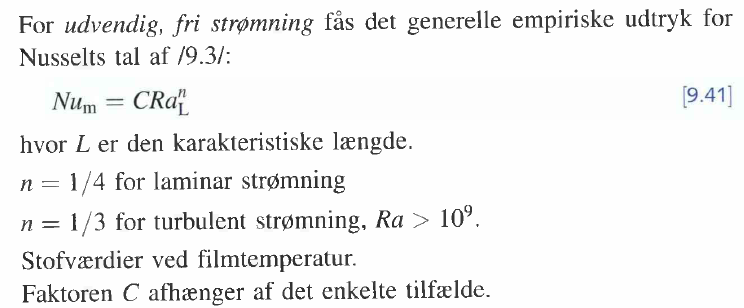

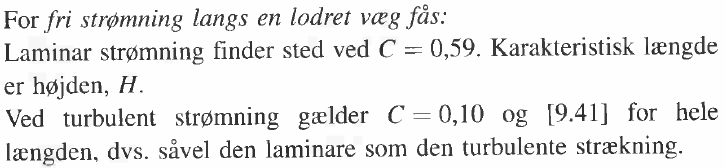

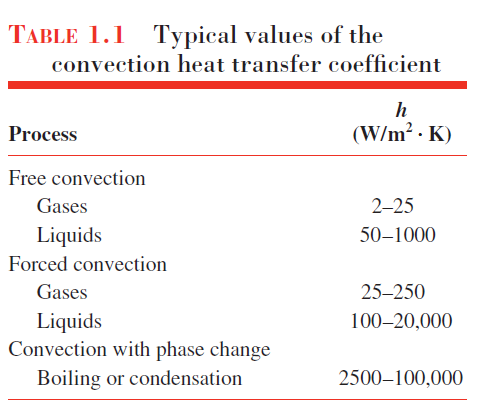


clear all
fluid = 'Air'

fluid = 'Air'

CoolProp = py.importlib.import_module('CoolProp.CoolProp');
P = 101325; % Pascal eller 1e5 %surface pressure

T_luft = 20 +273.15;
T_v = 37.5 +273.15 ; % start gæt på væg temperaturen
syms h_luft

g = 9.82;
w_tot = 0.555; %højden af radiatoren
C = 0.59; % til Nussels tal for fri strømning langs en lodret væg
h_start = 10; % start gæt for varmeovergangstallet, W/(m^2*K)

% interation = 10; % antal gange loopet skal køre


T_fluid = (T_v + T_luft)/2; % middel film temeperatur
mu = CoolProp.PropsSI('viscosity', 'P', P, 'T', T_fluid, fluid); %Dynamisk viscositet
rho = CoolProp.PropsSI('D', 'P', P, 'T', T_fluid, fluid); %Densitet
nu = mu/rho;
% nu = 15.06e-6; % ved 20 grad
k_luft = CoolProp.PropsSI('conductivity', 'P', P, 'T', T_fluid, fluid); %thermalConductivity
mu = CoolProp.PropsSI('viscosity', 'P', P, 'T', T_fluid, fluid); %Dynamisk viscositet
c_p = CoolProp.PropsSI('Cpmass', 'P', P, 'T', T_fluid, fluid); %specificHeat_p

beta = 1/T_fluid; %volumenudvidelseskoefficienten % [1/K]


Gr = g * beta * (T_v - T_luft)/nu^2;
Pr = mu * c_p / k_luft;

Ra_L = Gr * Pr;
% if Ra_L < 1e9
n = 1/4;
% else
% n = 1/3;
% end

Nu_m = C * Ra_L^n; %== 4/3 * (Gr/4)^(1/4) * g*Pr
h_eq = h_luft == Nu_m/w_tot * k_luft;

T_v = solve(h_eq, T_v) %, ReturnConditions=true)

 
T_v =
 
Empty sym: 0-by-1
 


vpa(T_v - 273.15, 5)

 
ans =
 
Empty sym: 0-by-1
 




% disp('end loop')
% T_v - 273.15
% h_luft

h = 10 

clear all
CoolProp = py.importlib.import_module('CoolProp.CoolProp');

h = 10;
g = 9.82;
w_tot = 0.555; %højden af radiatoren
l_tot = 1.18

l_tot = 1.1800

k = 177; %konducteviteten for alu tabel A.1
N = 66; %antal finner per side
w = 0.465; %højden af findenen
A_t_rad = w_tot * l_tot %arealet af radiatoren

A_t_rad = 0.6549

L = 0.03; %længden af finnen
T =  0.0005; % tykkelsen af finnen
% h_luft = 10; %convection heat transfer coeffecient = 10  from table 1.1
% h_luft = 4.9115; %found in calculation below from a start guess on the film temperature
L_c = L + T/2

L_c = 0.0302

A_f = 2*w*L_c %finne arealet

A_f = 0.0281

A_b = w_tot*l_tot - w*T*N %arealet af basen

A_b = 0.6396

A_t = N*A_f + A_b %total areal finner

A_t = 2.4963

A_c = w*T

A_c = 2.3250e-04

% P = 2*w + 2*T
% m = sqrt(h_luft*P/(k*A_c))


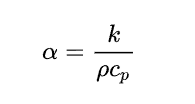

A_vand =  w * N/2 * (8e-3 * 3e-3)

A_vand = 3.6828e-04

P_ambient = 101300

P_ambient = 101300

% L = w * N + 4*1.70

syms c
c_vand = c;

vand = 'Water';
T_ind = 47 + 273.15

T_ind = 320.1500

T_ud = 28 + 273.15

T_ud = 301.1500

T_vand = (T_ind + T_ud)/2

T_vand = 310.6500

T_vand_s = T_vand

T_vand_s = 310.6500

T_vand_film = (T_vand + T_vand_s)/2

T_vand_film = 310.6500


% k_luft = CoolProp.PropsSI('conductivity', 'P', P, 'T', T_vand_film, vand); %thermalConductivity
k_vand = CoolProp.PropsSI('L', 'P', P_ambient, 'T', T_vand_film, vand); %thermalConductivity

eta_vand = CoolProp.PropsSI('V', 'P', P_ambient, 'T', T_vand_film, vand);
c_p_vand = CoolProp.PropsSI('Cpmass', 'P', P_ambient, 'T', T_vand_film, vand);
rho = CoolProp.PropsSI('D', 'P', P_ambient, 'T', T_vand_film, vand); %Densitet
nu_vand = eta_vand/rho;
% Pr = eta_vand * c_p_vand / k_vand
Re = c_vand* L/nu_vand

$$Re = \frac{1770887431076116955136\,c}{40691649611427125}$$

% h_vand = 
% R_conv = 1/(h_vand * A_vand)


R_cond = 1/(k*A_vand)

R_cond = 15.3408


% eta_f = tanh(m*L_c) / (m*L_c)
% eta_0 = 1 - (N  * A_f) / A_t * (1 - eta_f)
% A_t = N*A_f + A_b
% R_finner = 1/(eta_0 * h_luft * A_t)


% R_tot = R_conv + R_cond + R_finner



% clear all
fluid = 'Air'

fluid = 'Air'

CoolProp = py.importlib.import_module('CoolProp.CoolProp');
P = 101325; % Pascal eller 1e5 %surface pressure

T_luft = 20 +273.15;
T_v = T_luft + 37.5; % start gæt på væg temperaturen
syms h_luft

g = 9.82;
w_tot = 0.555; %højden af radiatoren
C = 0.59; % til Nussels tal for fri strømning langs en lodret væg
% h_luft = 10; % start gæt for varmeovergangstallet, W/(m^2*K)

h_plot = [];
T_plot = [];

% Ts = (2:2:20)+273.15;
% Ts = linspace(1,40,40)+273.15
interation = 1; % length(Ts) % antal gange loopet skal køre
for i = 1:interation
    % i
    % T_v = Ts(i);
    T_fluid = (T_v + T_luft)/2; % middel film temeperatur
    mu = CoolProp.PropsSI('viscosity', 'P', P, 'T', T_fluid, fluid); %Dynamisk viscositet
    rho = CoolProp.PropsSI('D', 'P', P, 'T', T_fluid, fluid); %Densitet
    nu = mu/rho;
    % nu = 15.06e-6; % ved 20 grad
    k_luft = CoolProp.PropsSI('L', 'P', P, 'T', T_fluid, fluid); %thermalConductivity
    mu = CoolProp.PropsSI('viscosity', 'P', P, 'T', T_fluid, fluid); %Dynamisk viscositet
    c_p_luft = CoolProp.PropsSI('Cpmass', 'P', P, 'T', T_fluid, fluid); %specificHeat_p
    alpha = k_luft/(rho * c_p_luft)
    beta = 1/T_fluid; %volumenudvidelseskoefficienten % [1/K]


    if rem(i,2) == 0  % statements to execute for even m(i)
        syms T_v
    else
        syms h_luft
    end

    Gr = g * beta * (T_v - T_luft)*w^3/nu^2;
    Pr = mu * c_p_luft / k_luft

    Ra_test = g * beta * (T_v - T_luft)*w^3/(nu * alpha)

    Ra_L = Gr * Pr
    if rem(i,2) == 1  % statements to execute for even m(i)
        if Ra_L < 1e9
            n = 1/4;
        else
            n = 1/3;
        end
    end


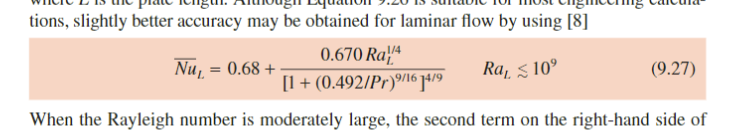

    % Nu_m = C * Ra_L^n %fra den danske termo bog
    Nu_m = 0.68 + (0.670 * Ra_L^(1/4))/(1 + (0.492/Pr)^(9/16))^(4/9) % eq 9.27
    % Nu_eq = h_luft*L/k_luft = 4/3 * (Gr/4)^(1/4) * g*Pr

    h_eq = 0 == Nu_m/w * k_luft - h_luft;

    if rem(i,2) == 0 % statements to execute for even m(i)
        T_v = solve(h_eq, T_v);
        T_v = double(T_v);
        T_plot(end+1) = T_v;
    else
        h_luft = solve(h_eq, h_luft);
        h_luft = double(h_luft);
        h_plot(end+1) = h_luft;
        
    end
    
end

alpha = 2.3920e-05

Pr = 0.7056

Ra_test = 2.9403e+08

Ra_L = 2.9403e+08

Nu_m = 67.9726

disp('end loop')

end loop


T_v_C = T_v - 273.15

T_v_C = 57.5000

h_luft

h_luft = 3.9852


P_w = 2*w;
m = sqrt(h_luft*P_w/(k*A_c))

m = 9.4900

eta_f = tanh(m*L_c) / (m*L_c) % eq (3.95)

eta_f = 0.9734

C1 = 1 %1 + (eta_f * h*A_f * R_tc/Acb) eq 3.110b

C1 = 1

eta_0 = 1 - (N  * A_f) / A_t * (1 - eta_f) % (3.107) eller 3.110a med /C1

eta_0 = 0.9802

1 - (10 * 0.00995 / 0.109) * (1 - 0.96)

ans = 0.9635

A_t = N*A_f + A_b

A_t = 2.4963

R_finner = 1/(eta_0 * h_luft * A_t)

R_finner = 0.1025


% plot(linspace(-10,10,length(Ts)), Tx)
% yline(min(h_plot))
% grid("minor")
R_tot = R_finner

R_tot = 0.1025

q_fin = (T_v - T_luft)/R_finner

q_fin = 365.6793

% q_2_sider_fin = q_fin*2

q_2_sider_fin = 731.3586


R_plade = 1/(h_luft * A_t_rad)

R_plade = 0.3832

q = 97.8713

% q_2_sider = q*2

q_2_sider = 195.7426

Radiation

sigma = 5.670374419 * 10^-8; % J/K %stefan-boltzman konstant
epsilon = 0.9; % emmission factor

q_rad = epsilon * sigma * (T_v^4 - T_luft^4) * A_t_rad % = h_r * A_plate * (T_2 - T_sur) % 

q_rad = 152.6628


R_rad = (T_v - T_luft)/q_rad

R_rad = 0.2456


R_tot_plade = 1/(1/R_plade + 1 / R_rad)

R_tot_plade = 0.1497

q_plade = (T_v - T_luft)/R_tot_plade

q_plade = 250.5341


q_tot = (q_fin + q_plade)*2

q_tot = 1.2324e+03

Vandstrømmen til radiatoren - energi ligning


$$\begin{array}{l}
q_m \cdot h_1 =q_m \cdot h_2 +q_{\mathrm{tot}} \\
q_m \left(h_1 -h_2 \right)=q_{\mathrm{tot}} \\
q_m =\frac{q_{\mathrm{tot}} }{\left(h_1 -h_2 \right)}\\
h=c_p \cdot T
\end{array}$$


P_vand = 1e5 * 1.4;
c_p_vand_ind = CoolProp.PropsSI('Cpmass', 'P', P_vand, 'T', T_ind, vand);
c_p_vand_ud = CoolProp.PropsSI('Cpmass', 'P', P_vand, 'T', T_ud, vand);

h_1 = c_p_vand_ind * T_ind

h_1 = 1.3384e+06

h_2 = c_p_vand_ud * T_ud

h_2 = 1.2589e+06

q_m = q_tot / (h_1 - h_2)

q_m = 0.0155